# Descending 1_CCRN_1_cat 

Read reaction network

foldernam = "Evolution - Praful\"

foldernam = "Evolution - Praful\"

filnam = foldernam +  "1_CCRN_1_cat"

filnam = "Evolution - Praful\1_CCRN_1_cat"

model_nam = "1-CCRN-1-cat"

model_nam = "1-CCRN-1-cat"

[num_spec,species,comp_vec,rxn_rate,G] = extract_rxn_net(filnam);

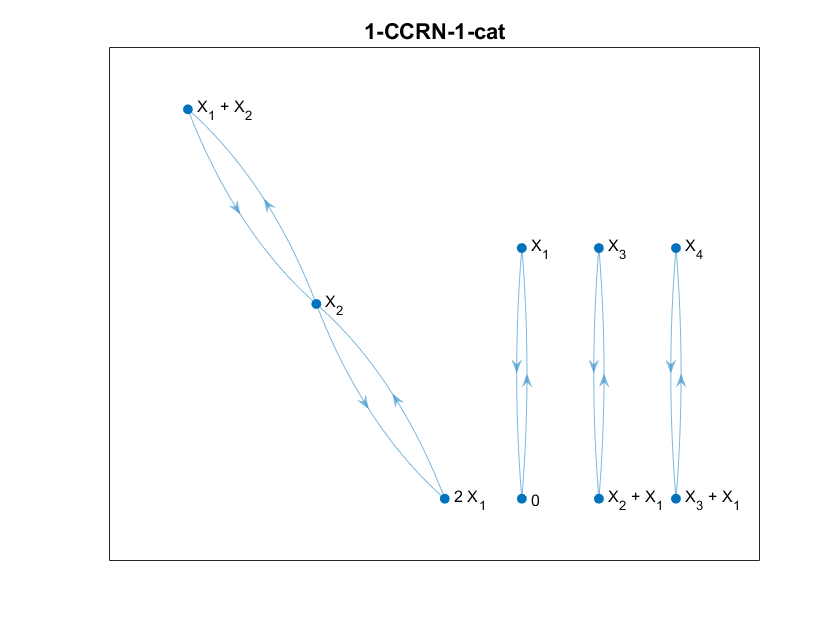

plotter(G,model_nam)
saveas(gcf,foldernam + 'Plots\'+ model_nam + '_hypergraph.png')

%Get Hamiltonian
Ham = get_Hamiltonian(num_spec,comp_vec,rxn_rate)

$$Ham = 2.3000\,{\mathrm{e}}^{p_{1}}+q_{3}\,\left(2\,{\mathrm{e}}^{p_{1}+p_{2}-p_{3}}-2\right)+q_{4}\,\left(2\,{\mathrm{e}}^{p_{1}+p_{3}-p_{4}}-2\right)+q_{1}\,\left(5.4500\,{\mathrm{e}}^{-p_{1}}-5.4500\right)+{q_{1}}^{2}\,\left({\mathrm{e}}^{p_{2}-2\,p_{1}}-1\right)+q_{2}\,\left(8.3000\,{\mathrm{e}}^{p_{1}}-8.3000\right)+q_{2}\,\left(2\,{\mathrm{e}}^{2\,p_{1}-p_{2}}-2\right)+q_{1}\,q_{2}\,\left(2\,{\mathrm{e}}^{-p_{1}}-2\right)+q_{1}\,q_{2}\,\left({\mathrm{e}}^{p_{3}-p_{2}-p_{1}}-1\right)+q_{1}\,q_{3}\,\left({\mathrm{e}}^{p_{4}-p_{3}-p_{1}}-1\right)-2.3000$$


%get functions derived from the Hamiltonian needed for the descent
Extract_Hamiltonian

%Get MAK polynomials and the jacobian
[MAK, jac, MAK_fun, jac_fun] = get_MAK(dHamdp,Ham_qp_mix,num_spec);

$$MAK = \left(\begin{array}{c} 12.3000\,q_{2}-5.4500\,q_{1}+2\,q_{3}+2\,q_{4}-3\,q_{1}\,q_{2}-q_{1}\,q_{3}-2\,{q_{1}}^{2}+2.3000\\ {q_{1}}^{2}-q_{2}\,q_{1}-2\,q_{2}+2\,q_{3}\\ 2\,q_{4}-2\,q_{3}+q_{1}\,q_{2}-q_{1}\,q_{3}\\ q_{1}\,q_{3}-2\,q_{4} \end{array}\right)$$

MAK_fun_t = function_handle with value:
    @(t,in2)[in2(1,:).*(-1.09e+2./2.0e+1)+in2(2,:).*(1.23e+2./1.0e+1)+in2(3,:).*2.0+in2(4,:).*2.0-in2(1,:).*in2(2,:).*3.0-in2(1,:).*in2(3,:)-in2(1,:).^2.*2.0+2.3e+1./1.0e+1;in2(2,:).*-2.0+in2(3,:).*2.0-in2(1,:).*in2(2,:)+in2(1,:).^2;in2(3,:).*-2.0+in2(4,:).*2.0+in2(1,:).*in2(2,:)-in2(1,:).*in2(3,:);in2(4,:).*-2.0+in2(1,:).*in2(3,:)]



%save Hamiltonian data to file
save(foldernam + 'Data\' + model_nam + '_Ham.mat')


%get roots --- later replace this with Bertini
get_roots_2D

$$pos\_root\_arr = \left(\begin{array}{cccc} 1 & 0.5000 & 0.2500 & 0.1250\\ 2 & 2 & 2 & 2\\ 1.1500 & 0.6612 & 0.3802 & 0.2186 \end{array}\right)$$

$$pos\_root\_arr = \left(\begin{array}{cccc} 1 & 0.5000 & 0.2500 & 0.1250\\ 2 & 2 & 2 & 2\\ 1.1500 & 0.6612 & 0.3802 & 0.2186 \end{array}\right)$$

x_ic_arr =     1.1493    0.6606    0.3796    0.2180
    1.1507    0.6619    0.3809    0.2193


%saveas(gcf,foldernam + 'Plots\'+model_nam+'_stability.png')

spec_arr = 1:4

spec_arr =      1     2     3     4


sad_idx

sad_idx = 3

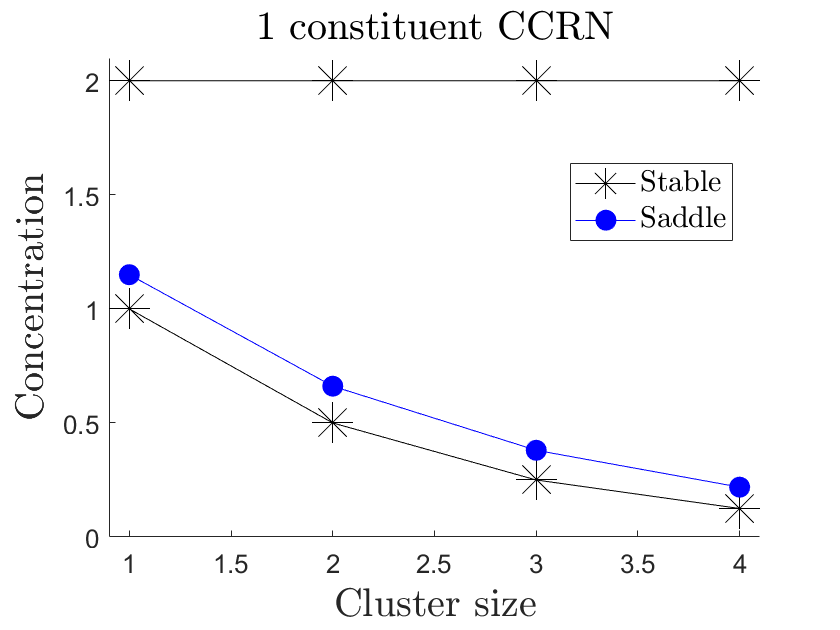

figure()
%lb = ; ub = 4;
hold on
plot(spec_arr, pos_root_arr(stab_idx(1),:),'k-*','MarkerSize',20,'MarkerFaceColor','k')
plot(spec_arr, pos_root_arr(sad_idx(1),:),'b-o','MarkerSize',10,'MarkerFaceColor','b')
%plot(pos_root_arr(2,1),pos_root_arr(2,2),'rs','MarkerSize',10,'MarkerFaceColor','r')
for i = 2:size(stab_idx,1)
    plot(spec_arr, pos_root_arr(stab_idx(i),:),'k-*','MarkerSize',20)
end
for i = 2:size(sad_idx,1)
    plot(spec_arr, pos_root_arr(sad_idx(i),:),'b-o','MarkerSize',10,'MarkerFaceColor','b')
end
hold off
%legend('Stable roots','Saddle roots','All roots','location','north')
h1=legend('Stable','Saddle','location','best');
%h1=legend('Stable','Saddle','location','best');
set(h1,'Interpreter','latex');
h1.FontSize = 15;
ax=gca;
ax.FontSize = 13;

xlabel('Cluster size','interpreter','latex','FontSize',20)
ylabel('Concentration','interpreter','latex','FontSize',20)
lim = double([min(pos_root_arr(:,1))-0.2  max(pos_root_arr(:,1))+0.2]);
xlim([0.9,4.1])
lim = double([min(pos_root_arr(:,2))-0.2  max(pos_root_arr(:,2))+1]);
ylim([0 2.1])
%grid on
title('1 constituent CCRN','Interpreter','latex','FontSize',20)

## Heteroclinic Network

Data saved in

'Examples\Data\' + model_name + '_hcnet.mat'

Heteroclinic_network

Unrecognized function or variable 't_max'.

Error in Heteroclinic_network (line 12)
hc_traj_arr = odeintegrator(@(t,q)MAK_fun_t(t,q), x_ic_arr, t_max);

%save hc plot
saveas(gcf,foldernam +'Plots/'+model_nam+'_hcnet.png')

%Save hc_net data
save(foldernam + 'Data\' + model_nam + '_hcnet.mat','pos_root_arr', 'hc_net', 'hc_traj_arr', 'stab_idx', 'sad_idx','t_arr')
